# Model Fidelity in Simscape Battery

Copyright 2023-2024 The MathWorks, Inc.

This script creates and compares two battery packs with different model fidelity. Subsequently, the results are compared in terms of calculation time.

For more information regarding the electrical and thermal cell models for Simscape Battery, see the documentation for the blocks [Battery (Table-Based)](https://www.mathworks.com/help/sps/ref/batterytablebased.html) and [Battery Equivalent Circuit](https://www.mathworks.com/help/simscape-battery/ref/batteryequivalentcircuit.html?s_tid=doc_ta)

## Understanding How Model Fidelity Works

In Simscape Battery, one can select from three model fidelities when constructing a module, module assembly, or battery pack. These fidelities differ in the number of models used to characterize the components of the battery system. The distinctions between fidelities are visually exemplified in the accompanying figure, which depicts a moudle with a 3p2s configuration.

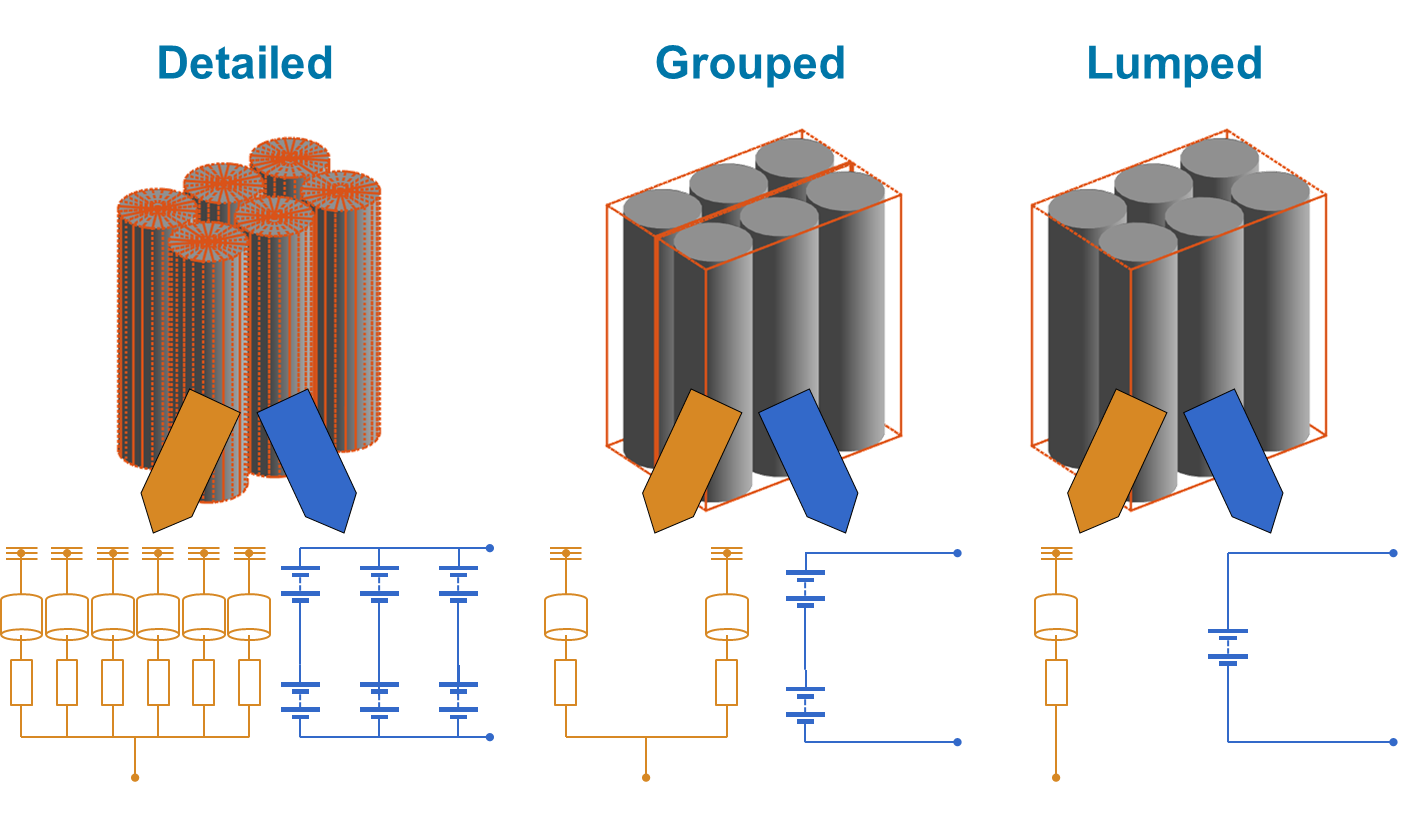

**Detailed Model Fidelity**: This approach is used to examine gradients in temperature, current, or voltage within a pack. For a module like the one described, Simscape Battery assigns six thermal and six electrical models, one for each cell (**12 models** in total).

**Lumped Model Fidelity:** Suitable when gradients within the module are not a concern. This method assumes uniform cell behavior. Simscape uses one thermal and one electrical model for the entire module, leading to a requirement of just **2 models** for simulation.

**Grouped** **Model Fidelity:** This middle-ground fidelity allows for grouping parallel assemblies, each assigned one thermal and one electrical model. For the 3p2s module example, the simulation requires **4 models**, as smaller groupings than parallel assemblies are not permitted.

% Clear the MATLAB workspace
clear

% Set the MATLAB Path to the same folder as this script (this is needed later when creating the libraries)
if(~isdeployed); cd(fileparts(matlab.desktop.editor.getActiveFilename)); end

## Building a Lumped and a Detailed Battery Pack

To demonstrate the difference in computation speeds between **Lumped** and **Detailed** fidelity, each strategy is utilized to simulate the same battery pack. The pack comprises 8 modules, with each module containing 24 pouch cells in a 2p12s electrical configuration (192 cells in total). The modules are connected in series and arranged into two rows. As the geometry and cell properties are consistent, they are initialized once and subsequently applied to both modeling approaches.

% Import Simscape Battery Builder (This line is required in every section)
import simscape.battery.builder.*

% Create geometry
pouchGeom = PouchGeometry(Height=simscape.Value(0.1,"m"), Length=simscape.Value(0.5,"m"),TabLocation="Opposed");

% Create cell
pouchCell = Cell(Geometry=pouchGeom,Capacity=simscape.Value(80,'Ah'),Energy=simscape.Value(300,'Wh'));

% Select and set up cell model
pouchCell.CellModelOptions.CellModelBlockPath                  = "batt_lib/Cells/Battery Equivalent Circuit";
pouchCell.CellModelOptions.BlockParameters.ThermalModel        = "LumpedThermalMass";

% Create Parallel Assembly
parallelAssem = ParallelAssembly("Cell",pouchCell,"StackingAxis","Y","InterCellGap",simscape.Value(0.5,'mm'),"NumParallelCells",2);

Build a **lumped** battery pack. This pack has 8 thermal models (one for each module) and 8 electrical models (one for each module):

packLmp = createPackVariable(parallelAssem,"Lumped");

Build a **detailed** battery pack. This pack has 192 thermal models (one for each cell) and 192 electrical models (one for each cell):

packDet = createPackVariable(parallelAssem,"Detailed");

## Visualizing the Pack Fidelities

Model fidelity comparisons can be conducted using the `BatteryChart` function.

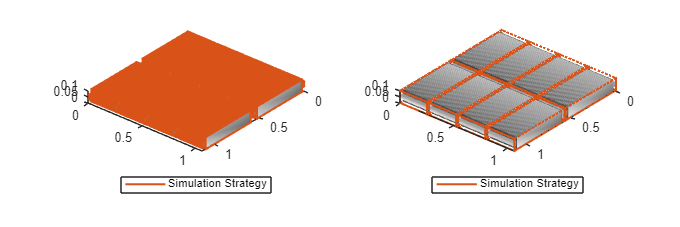

% Import Simscape Battery Builder (This line is required in every section)
import simscape.battery.builder.*

% Create tiled layout
f = uifigure(Name='Model Fidelities',Color="w",Units="centimeters",Position=[2,2,18,6]);
tl = tiledlayout(1,2,"Parent",f); nexttile(tl)

% Plot both batteies with their Simulation Strategy:
BatteryChart(Parent = tl, Battery=packDet,SimulationStrategyVisible="On"); nexttile(tl)
BatteryChart(Parent = tl, Battery=packLmp,SimulationStrategyVisible="On"); clear f tl

The batteries are also integrated with a cooling plate, which offers options for varying model resolutions as demonstrated below. The lumped pack is coupled with a lumped plate. The detailed pack is coupled with a plate discretized in 16 sections (2 for each module row). Number of discretizations in X and Y can be varied as desired. For more information see [Connect Cooling Plate to Battery Blocks](https://de.mathworks.com/help/simscape-battery/ug/coonect-cooling-plate-to-battery-module-parallel-assembly.html).

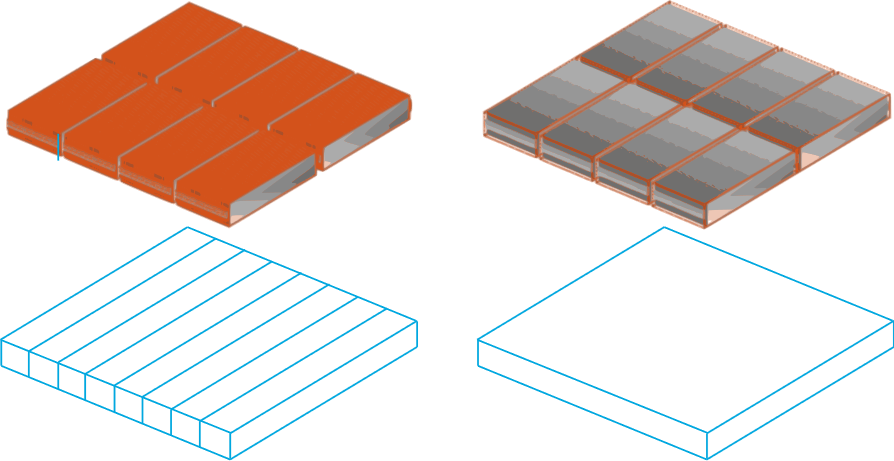

## Generating Library Files for the Lumped and Detailed Batteries

The libraries are generated using the `buildBattery` function. The code section below checks for the presence of folders containing the libraries; if not found, it proceeds to create the libraries. To rebuild the libraries, the "old" library folders must be deleted first.

% Import Simscape Battery Builder (This line is required in every section)
import simscape.battery.builder.*

% If there is no folder where to store the library, create one
if ~exist('BatteryLmp', 'dir')
    mkdir('BatteryLmp'); 
    buildBattery(packLmp,LibraryName="packLumped",  Directory = strcat(cd,"\BatteryLmp\"),MaskParameters="VariableNames");
end

Generating Simulink library 'packLumped_lib' in the output directory 'C:\Users\gschrabe\OneDrive - MathWorks\Customers14_20\Demos\FastElectricalSimulations\_5_Model_Fidelity\5_5_Batteries\BatteryLmp' ...
Generating MATLAB script 'packLumped_param' in the current directory 'C:\Users\gschrabe\OneDrive - MathWorks\Customers14_20\Demos\FastElectricalSimulations\_5_Model_Fidelity\5_5_Batteries\BatteryLmp'



if ~exist('BatteryDet', 'dir')
    mkdir('BatteryDet');
    buildBattery(packDet,LibraryName="packDetailed",Directory = strcat(cd,"\BatteryDet\"),MaskParameters="VariableNames");
end

Generating Simulink library 'packDetailed_lib' in the output directory 'C:\Users\gschrabe\OneDrive - MathWorks\Customers14_20\Demos\FastElectricalSimulations\_5_Model_Fidelity\5_5_Batteries\BatteryDet' ...
Generating MATLAB script 'packDetailed_param' in the current directory 'C:\Users\gschrabe\OneDrive - MathWorks\Customers14_20\Demos\FastElectricalSimulations\_5_Model_Fidelity\5_5_Batteries\BatteryDet'



% Add the library folder to the current path (it will be required later)
addpath(genpath(strcat(cd,"\BatteryLmp\"))); addpath(genpath(strcat(cd,"\BatteryDet\")));

## Building Charge and Discharge Models

The generated libraries are employed to simulate a charge and discharge scenario on the battery. The pack libraries are utilized to construct two distinct model —one with lumped and one with detailed battery— to compare their calculation speeds. These models are created by scripting the assembly of necessary Simscape blocks.

Create a a Simulink model to simulate a simple charge and discharge scenario with the **lumped battery** pack:

% Create and open a new model
open_system(new_system("batteryLmpModel"));

% Assemble all other remaining components and connect the components
assembleModel("batteryLmpModel", "packLumped");

% Set the stop time 
set_param(gcs,'StopTime','9500');
set_param(getActiveConfigSet("batteryLmpModel"),'SimscapeLogType','all','SimscapeLogSimulationStatistics','on','SimscapeLogLimitData','off');

Create a a Simulink model to simulate a simple charge and discharge scenario with the **detailed battery** pack:

% Create and open a new model
open_system(new_system("batteryDetModel"));

% Assemble all other remaining components and connect the components
assembleModel( "batteryDetModel", "packDetailed");

% Set the stop time 
set_param(gcs,'StopTime','9500');
set_param(getActiveConfigSet( "batteryDetModel"),'SimscapeLogType','all','SimscapeLogSimulationStatistics','on','SimscapeLogLimitData','off');

## Simulating the Models

After the lumped and detailed models are created, they are ready for simulation to enable comparison of their results and performance in the following section. To carry out the simulation, the parametrization script provided with the libraries is exectued. Certain parameters within this script, like plate discretization and specific cell properties, are adjusted to more accurately represent the battery being simulated.

To simulate the **lumped** model, configure the discretization values for the plate along the X and Y to one. This effectively treats the plate as a lumped thermal mass as shown in the section *Visualizing the Pack Fidelities. *The simulation results are stored in the variable `outLmp`.

% First parametrize and simulate the Lumped model
packLumped_param;

% Assign a realistic thermal mass and capacity for the considered cell dimensions
ModuleType1.BatteryThermalMassCell = 2500;      % J/K
ModuleType1.BatteryCapacityCell    = 80;        % Ah

% Set the dirscretization of the plate to (1,1) -> Lumped plate
CoolingPlateBottom.plateDimX = 1; CoolingPlateBottom.plateDimY = 1;
CoolingPlateBottom.nChannels = 16;

% Simulate the model and collect
outLmp         = sim("batteryLmpModel");

To simulate the **detailed** model, configure the discretization values for the plate along the X to one  and along Y to 16. This effectively discretizes the plate in 16 slices as shown in the section *Visualizing the Pack Fidelities. *The simulation results are stored in the variable `outDet`.

% First parametrize and simulate the Lumped model
packDetailed_param;

% Assign a realistic thermal mass
ModuleType1.BatteryThermalMassCell = 2500;      % J/K
ModuleType1.BatteryCapacityCell    = 80;        % Ah

% The plate will be lumped:
CoolingPlateBottom.plateDimX = 1; CoolingPlateBottom.plateDimY = 16;
CoolingPlateBottom.nChannels = 16;

% Simulate the model and collect the Timing Info
outDet = sim("batteryDetModel");

## Comparing the Models

First, the results of both simulation are compared grapically

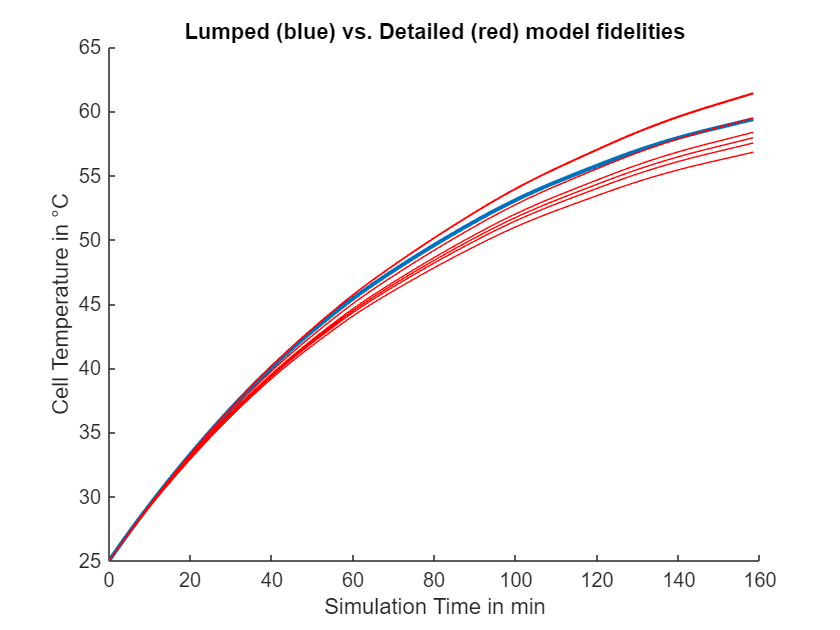

figure('Name','Module Temperature Comparison'); hold on; 
plot(outLmp.simlog.Pack.ModuleAssembly1.Module1.Cell1.batteryTemperature.series.time/60,outLmp.simlog.Pack.ModuleAssembly1.Module1.Cell1.batteryTemperature.series.values('degC'),'LineWidth',2)
plot(outDet.simlog.Pack.ModuleAssembly1.Module1.batteryTemperature.series.time/60,outDet.simlog.Pack.ModuleAssembly1.Module1.batteryTemperature.series.values('degC'),'Color',[1,0,0]);
xlabel('Simulation Time in min'); ylabel('Cell Temperature in °C');
title('Lumped (blue) vs. Detailed (red) model fidelities');hold off;

The execution and compilation times for both models can be tabulated, facilitating the visualization of the speed gains of a lumped over a detailed simulation.

% Dispose the execution and compiling time for both models in a table
disp(compareModelTime(outDet.SimulationMetadata.TimingInfo, outLmp.SimulationMetadata.TimingInfo))

                                 Time for Detailed Model    Time for Lumped Model    Speed Gain
                                 _______________________    _____________________    __________

    Initialization phase in s            262.35                     46.578            "x5.63"  
    Execution phase in s                 9.2503                    0.88713            "x10.43" 



## Factors Impacting Calculation Speed

The number of models needed to simulate a battery pack depends on the selected model fidelity. More models yield richer simulation data but also increase computation time. Thus, it is essential to understand what the focus of the simulation is and choose the model fidelity accordingly.

Predicting the calculation speed gain from using a lumped model over a detailed one is not straightforward, as it is influenced by several factors, including:

- Total number of cells (determines the reduction in required number of models when switching from detailed to lumped)

- Cell model complexity (e.g. which electrical model is being used? RC1? RC2?)

- Are the thermal paths active? Which ones?

- What kind of cycle is being simulated?

## Subfunctions

This function builds the batteries based on the chosen model resolution:

function pack = createPackVariable(parallelAssem,ModelResolution)

    % Import Simscape Battery Builder (This line is required in every section)
    import simscape.battery.builder.*
    
    % Create Module with DETAILED model resolution
    module = Module("ParallelAssembly",parallelAssem,"NumSeriesAssemblies",12,"InterParallelAssemblyGap",simscape.Value(0.5,'mm'),"ModelResolution",ModelResolution);
    
    % Create the module assemblies (the one with 3 modules and the one with 2 modules)
    mdouleAssembly = ModuleAssembly("Module",repmat(module,1,2),"StackingAxis","X","InterModuleGap",simscape.Value(10,'mm'));
    
    % Assemble and plot the DETAILED pack
    pack = Pack("ModuleAssembly",repmat(mdouleAssembly,1,4),"StackingAxis","Y","InterModuleAssemblyGap",simscape.Value(20,'mm'));

    % Set the thermal resistance with the ambient
    pack.AmbientThermalPath  ="CellBasedThermalResistance";

    % Set the thermal rresistances to the plate
    pack.CoolantThermalPath    = 'CellBasedThermalResistance';
    pack.CoolingPlate          = "Bottom";
    pack.CoolingPlateBlockPath = "batt_lib/Thermal/Parallel Channels";
end

This function creates the Simscape models

function assembleModel(modelname, batteryLibraryPath)
% This function was built to assemble the battery model while keepin

batteryBlockPath = strcat(modelname,"/","Pack");

add_block(strcat(batteryLibraryPath,"/","Pack1"),batteryBlockPath,position=[0,0,220,220]);


% First generate the block paths required later on when adding the block.
% These path will be used to name/tag the blocks in the model
electricalRefBlockPath     = strcat(modelname,"/","ElectricalReference");
solverConfigBlockPath      = strcat(modelname,"/","Solver");
ambientTempSourceBlockPath = strcat(modelname,"/","Temperature Source");
cyclerBlockPath            = strcat(modelname,"/","Cycler");
addBlockPath               = strcat(modelname,"/","Addition");
StepBlockPath              = strcat(modelname,"/","Step");
reservoirIn                = strcat(modelname,"/","InputReservoir");
reservoirOut               = strcat(modelname,"/","OutputReservoir");
flowRateSource             = strcat(modelname,"/","flwRate");

% Add the blocks to the model
add_block("fl_lib/Electrical/Electrical Elements/Electrical Reference",electricalRefBlockPath, ...
           position=[45   240    60   255],orientation="down",ShowName = "off");
add_block("batt_lib/Cyclers/Cycler",cyclerBlockPath, ...
           position=[-100    90   -60   130],ShowName="off",orientation="right",configuration_option = 'simscape.battery.enum.cyclers.device_configuration.Galvanostat');
add_block("fl_lib/Thermal/Thermal Sources/Temperature Source",ambientTempSourceBlockPath, ...
           position=[100   240   128   280],ShowName="off",orientation="down");
add_block("fl_lib/Thermal Liquid/Elements/Reservoir (TL)",reservoirIn, ...
           position=[170   300   198   340],ShowName="off",orientation="down");
add_block("fl_lib/Thermal Liquid/Elements/Reservoir (TL)",reservoirOut, ...
           position=[230   300   260   340],ShowName="off",orientation="down");
add_block("fl_lib/Thermal Liquid/Sources/Flow Rate Source (TL)",flowRateSource, ...
           position=[170   250   210   290],ShowName="off",orientation="up");
add_block("fl_lib/Physical Signals/Functions/PS Add",addBlockPath, ...
           position=[-150    90  -126   130],ShowName="off",orientation="right");
add_block("fl_lib/Physical Signals/Sources/PS Step",strcat(StepBlockPath,"1"), ...
           position=[-250    60  -210   100],ShowName="off",orientation="right",initial_value='100',final_value='-100',step_time='3500')
add_block("fl_lib/Physical Signals/Sources/PS Step",strcat(StepBlockPath,"2"), ...
           position=[ -250   120  -210   160],ShowName="off",orientation="right",initial_value='0',final_value='200',step_time='6500')
add_block("nesl_utility/Solver Configuration",solverConfigBlockPath, ...
           position=[-150   190   -80   222]);

% Set flow rate source
set_param(flowRateSource,'source_type','foundation.enum.constant_controlled.constant');
set_param(flowRateSource,'flow_type','foundation.enum.mass_volumetric_flow.volumetric');
set_param(flowRateSource,'volumetric_flow_unit','lpm');
set_param(flowRateSource,'volumetric_flow','4');

% Get the handles of the block ports
batteryBlockHandles           = get_param(batteryBlockPath,"PortHandles");
electricalRefBlockHandles     = get_param(electricalRefBlockPath,"PortHandles");
solverConfigBlockHandles      = get_param(solverConfigBlockPath,"PortHandles");
ambientTempSourceBlockHandles = get_param(ambientTempSourceBlockPath,"PortHandles");
Step1BlockHandles             = get_param(strcat(StepBlockPath,"1"),"PortHandles");
Step2BlockHandles             = get_param(strcat(StepBlockPath,"2"),"PortHandles");
addBlockHandles               = get_param(addBlockPath,"PortHandles");
cyclerBlockHandles            = get_param(cyclerBlockPath,"PortHandles");
reservoirInBlockHandles       = get_param(reservoirIn,"PortHandles");
reservoirOutBlockHandles       = get_param(reservoirOut,"PortHandles");
flowRateSourceBlockHandles     = get_param(flowRateSource,"PortHandles");

% Connect the block ports as needed
add_line(modelname, cyclerBlockHandles.RConn(1),batteryBlockHandles.LConn(1),autorouting="smart");
add_line(modelname, cyclerBlockHandles.RConn(2),batteryBlockHandles.RConn(1),autorouting="smart");
add_line(modelname,batteryBlockHandles.RConn(1),electricalRefBlockHandles.LConn,autorouting="smart");
add_line(modelname,batteryBlockHandles.RConn(2),ambientTempSourceBlockHandles.LConn,autorouting="smart");
add_line(modelname, addBlockHandles.RConn,cyclerBlockHandles.LConn);
add_line(modelname, addBlockHandles.LConn(1),Step1BlockHandles.RConn);
add_line(modelname, addBlockHandles.LConn(2),Step2BlockHandles.RConn);
add_line(modelname,solverConfigBlockHandles.RConn, electricalRefBlockHandles.LConn,autorouting="smart");
add_line(modelname,reservoirInBlockHandles.LConn,flowRateSourceBlockHandles.LConn)
add_line(modelname,flowRateSourceBlockHandles.RConn,batteryBlockHandles.RConn(3))
add_line(modelname,reservoirOutBlockHandles.LConn,batteryBlockHandles.RConn(4))
end

This function creates the table to compare excecution and compile time:

function T= compareModelTime(tmInfDet,tmInfLmp)

% Create a table to store the results
T = table('Size',[2,3],'VariableNames',{'Time for Detailed Model','Time for Lumped Model','Speed Gain'},'RowNames',{'Initialization phase in s','Execution phase in s'},...
          'VariableTypes',{'double', 'double','string'});

% Update the table with the simulation results and plot it
T{1,1} = tmInfDet.InitializationElapsedWallTime;
T{2,1} = tmInfDet.ExecutionElapsedWallTime;
T{1,2} = tmInfLmp.InitializationElapsedWallTime;
T{2,2} = tmInfLmp.ExecutionElapsedWallTime;
T{1,3} = strcat("x", num2str(round(T{1,1}/T{1,2},2)));
T{2,3} = strcat("x", num2str(round(T{2,1}/T{2,2},2)));

end